#### BME 4400 Vanderbilt University

#### Professor Mark D. Does

# Backprojection Demos

## Point source projections

Before we get to *back*projection, let's consider forward projections, and let's start with a single point source.

clear all
close all

Create and display an $N \times N$ image with a single non-zero point. 

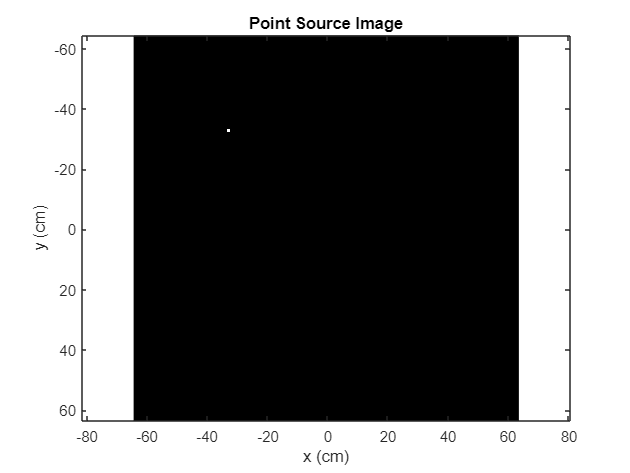

N = 128;
dx = 1; dy = 1; % arbitrary spatial resolution
x = -N/2:1:N/2-1;
y = -N/2:1:N/2-1;
IMG = zeros(N,N);
IMG(N/4,N/4) = 1; % single non-zero point. Location doesn't matter
figure(1), colormap(gray)
imagesc(y,x,IMG), axis('equal')
ylabel('y (cm)')
xlabel('x (cm)')
title('Point Source Image')

As created, the image intensity has no units, but we can treat it like a map of X-Ray attenuation coefficients, $\mu(x,y)$. Now consider an X-Ray system with parallel X-Ray beam at angle $\theta$ relative to the x-axis, as shown in this figure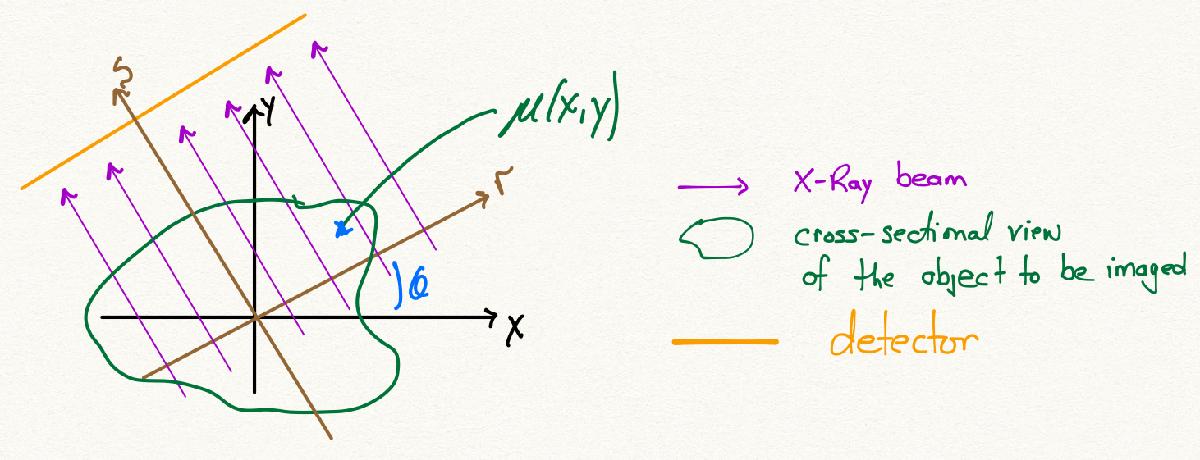

With a mono-energetic approximation, the X-Ray beam intensity at the detector is


$$I(r,\theta) = I_0 \exp\left[-\int_{-\infty}^\infty ds \, µ(x,y)\right]$$


because each X-Ray beam travels parallel to the $s$-axis at position $r$ (i.e., each of the purple lines in this figure is an X-Ray beam path), and these paths vary with respect to the $(x,y)$ coordinate system depending on angle $\theta$. If we log-transform the detector signal divided by the projection signal, $p(r,\theta)$, is simply the path integral of the attenuation coefficient map,


$$p(r,\theta) = -\log\left[\frac{I(r,\theta)}{I_0}\right] = -\int_{-\infty}^\infty ds \, µ(x,y)$$


The attenuation coefficient map can be transformed into the $(r,s)$ coordinate system, 


$$p(r,\theta) = -\int_{-\infty}^\infty ds \, µ(r\cos \theta -s \sin \theta,r \sin \theta + s \cos \theta)$$


This integral tranform from a map in $(x,y)$ to projections in the $(r,s)$ coordinate system is known a**s the Radon Tranform**. For all $r$ and $\theta$, $p(r,\theta)$ is called a *sinogram* -- weird name, but it will make sense shortly.

If $\theta = 0^{\circ}$, then the X-Ray beam is p**arallel with the columns** of the image matrix and the projection is **simply the sum along the columns** multiplied by the step size.

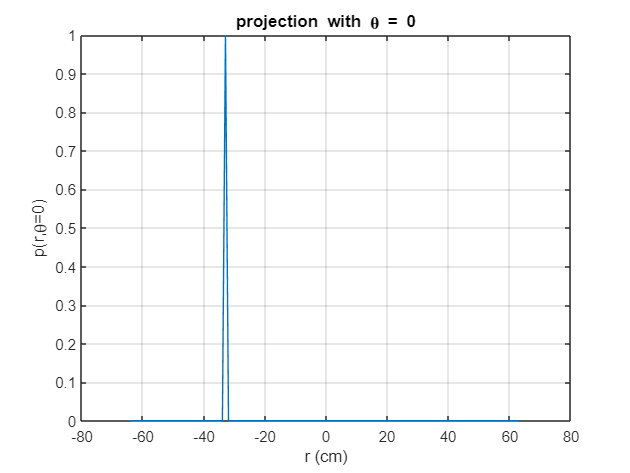

p0 = sum(IMG)*dy;
figure
plot(x,p0)
title('projection with \theta = 0')
xlabel('r (cm)')
ylabel('p(r,\theta=0)')
grid on

However, it's going to be a bit tedious to work this out for an arbitrary rotation angle, $\theta$. Fortunately, MATLAB has a built-in function that does the work for you -- `radon`. 

The `radon` function computes the sinogram from an image given** a number of projection angles, theta**

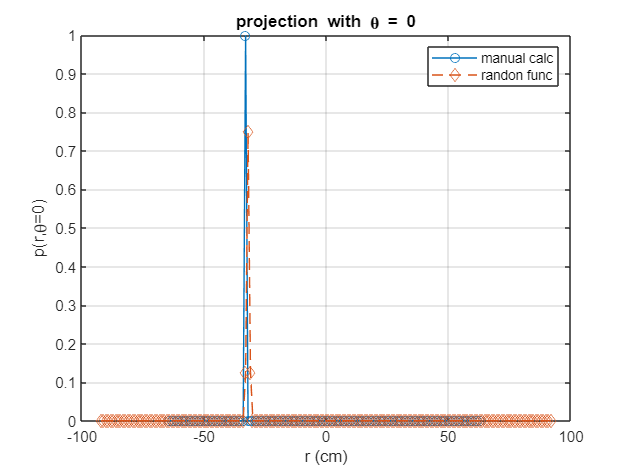

[p0_radon,r] = radon(IMG,0);
figure
plot(x,p0,'o-',r,p0_radon,'d--')
title('projection with \theta = 0')
xlabel('r (cm)')
ylabel('p(r,\theta=0)')
grid on
legend('manual calc', 'randon func')

Hmmm... not exactly the same thing? The reason is simply that the radon function starts by **interpolating the original image by a factor of **$2\times$ in each direction. 

More generally, we'll want the transform computed for many rotation angles

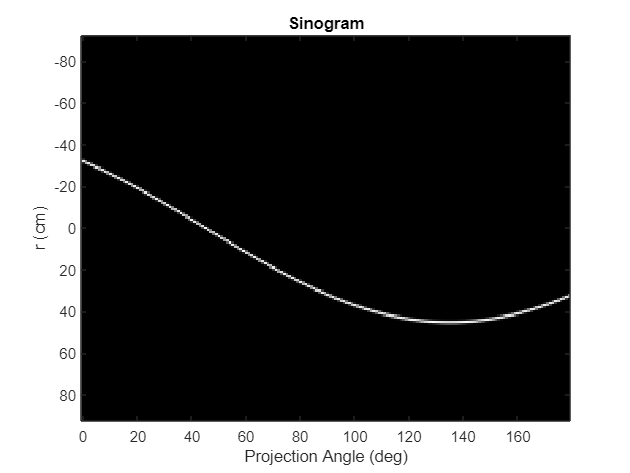

theta = [0:179]; % 180 projection angles ---- theta = # of projection angles
[p,r] = radon(IMG,theta);  % radon func add just number of pixels at each angle (diag = side*sqrt(2))
% p is a matrix of projections at different angles
% r is an index space in the radial direction (perpendicular to X-ray path)
figure, colormap(gray)
imagesc(theta,r,p), title('Sinogram')
ylabel('r (cm)')
xlabel('Projection Angle (deg)');

Now, the name *sinogram* starts to make more sense; a** single point in image space** maps to a s**inusoidal function**** in projection spac**e.

## Show how sinogram changes depending on the point positions

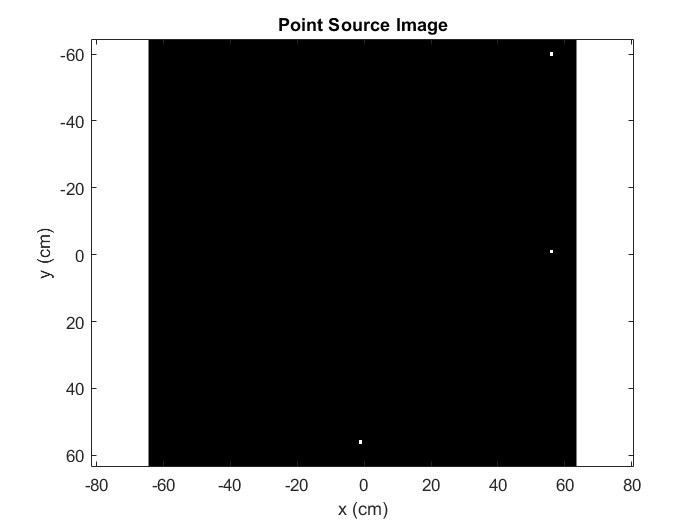

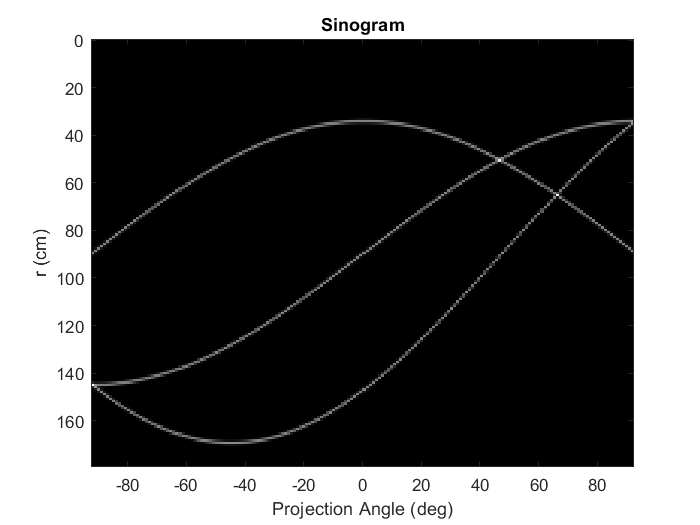

close all
% % create two non-overlapping figure windows
% h1 = figure(1);colormap(gray)
% h2 = figure(2);colormap(gray)
% P = get(h2,'Position');
% set(h2,'Position',P-[0 P(4) 0 0]);

for k = 1:8:N
    IMG = zeros(N,N);
    IMG(64,k) = 1;
    IMG(5,k) = 1;
    IMG(k,64) = 1;
    [p,r] = radon(IMG,theta); % radon tranform  % 3 point sources = 3 functions on sinogram
    figure(1)
    imagesc(y,x,IMG), axis('equal'), colormap('gray')
    ylabel('y (cm)')
    xlabel('x (cm)')
    title('Point Source Image')
    drawnow
    figure(2)
    imagesc(r,theta,p),title('Sinogram')
    colormap('gray')
    ylabel('r (cm)')
    xlabel('Projection Angle (deg)');
    drawnow
    pause(1)
end

Each point in image space, µ(x,y), maps to a sinusoidal function in the Sinogram

## Example sinogram from a phantom image

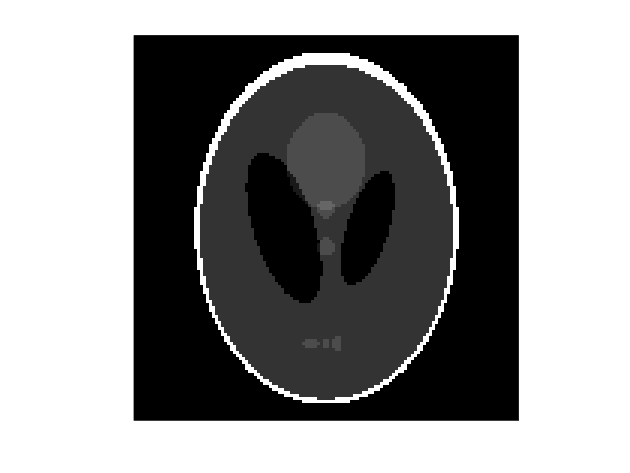

N = 128;
IMG = phantom(N);
figure
imagesc(IMG), axis('off'), axis('equal'), colormap('gray')

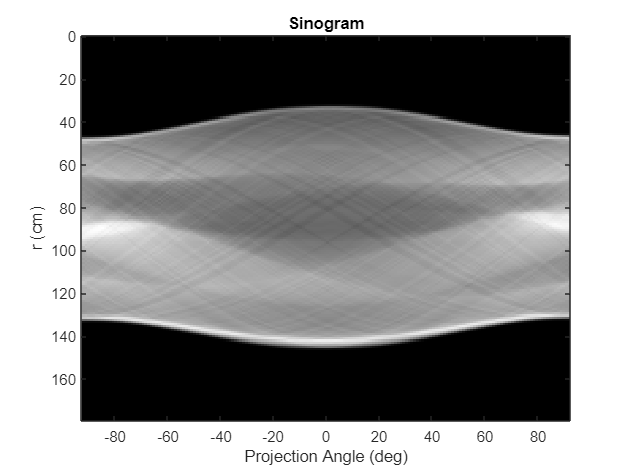

[p,r] = radon(IMG,theta); % theta = [0:179]; % 180 projection angles
figure, colormap(gray)
imagesc(r,theta,p), title('Sinogram')
ylabel('r (cm)')
xlabel('Projection Angle (deg)');

## Unfiltered backprojection, point source image

Look back at a single projection from a point source image -- it's a delta function. If you ***back*****project this delta function into **$(x,y)$** space, you'll get a line**. Again, MATLAB makes this easy by using the `iradon` function -- inverse Radon transform. To demonstrate:

N = 129;
IMGp = zeros(N,N);
IMGp((N+1)/2,(N+1)/2) = 1; % Single point image
imagesc(IMGp), axis('equal')
ylabel('y (cm)')
xlabel('x (cm)')
title('Point Source Image')


[p,r] = radon(IMGp,0); % 1 forward projection - theota = 0
figure(2), colormap(gray)

% backproject 1 projection
fb = iradon(p,0,'linear','none');

Here, "**linear" indicates the type of interpolation** in the backprojected image, and "none" indicates no filtering before backprojection. More on this below.

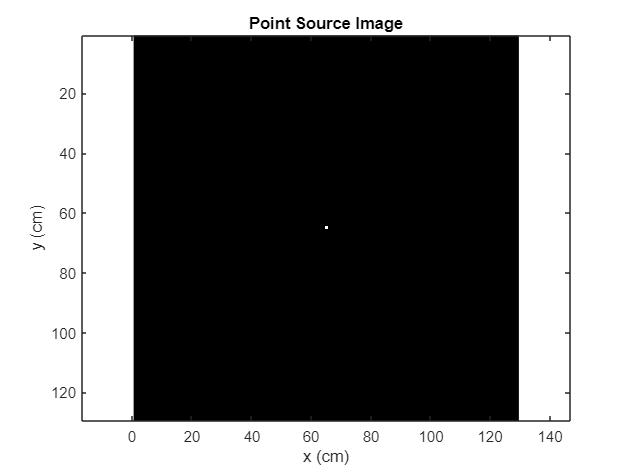

figure(1), colormap(gray)

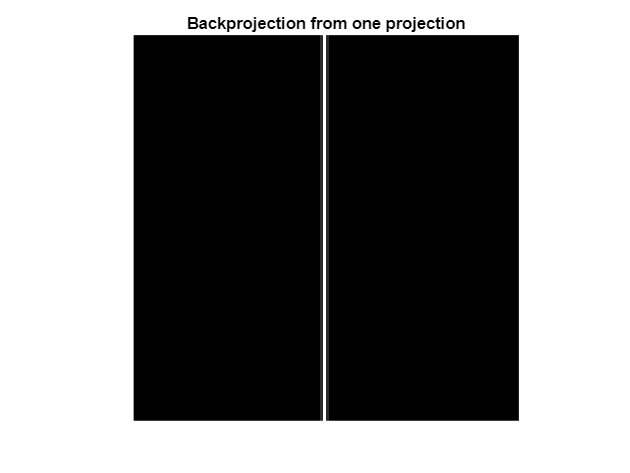

imagesc(fb), axis('off'), axis('equal')
title('Backprojection from one projection')

## unfiltered backrpojection -- varying number of projections

Now see the integration of many** back projections from different angles**. To make it easier to see, we'll use a surface rendering of this image.

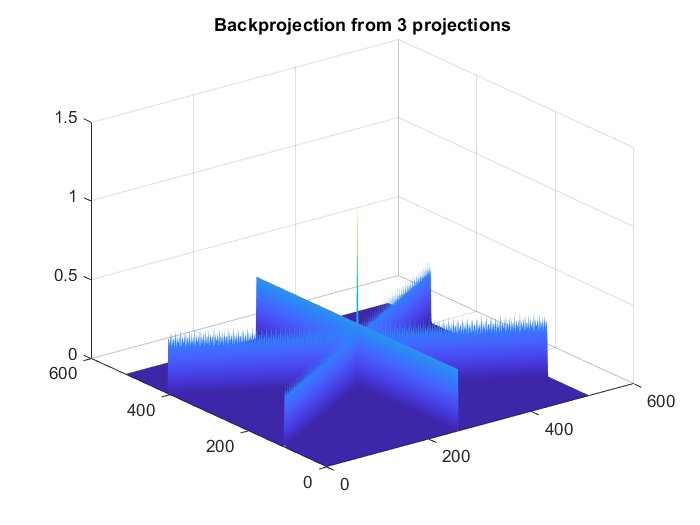

close all

for Np = 1:1:3
    kp = [0:180/Np:179];
    [p,r] = radon(IMGp,kp);
    hb = iradon(p,kp,'linear','none');
    h = surf(hb); set(h,'LineStyle','none','FaceColor','interp');
    %    imagesc(hb), axis('off'), axis('equal')
    title(['Backprojection from ',int2str(Np),' projections'])
    if Np <32
        pause(0.5)
    else
        pause(.1)
    end
    
end

We can see that wi**th a sufficient number of projection**s, a backprojected image of a point source looks like a point, but with a finite width. This is **the *****point spread function*** of a projection-backprojection "system"! 

- We have just convolved a Delta func (point source image) with the PSF of our system ==> result is PSF of our system

## Unfiltered backrpojection -- phantom image - RESULT = BLURRY

If we conv**olve this point spread function to a phantom ima**ge, we should expect a blurry version of the input image.

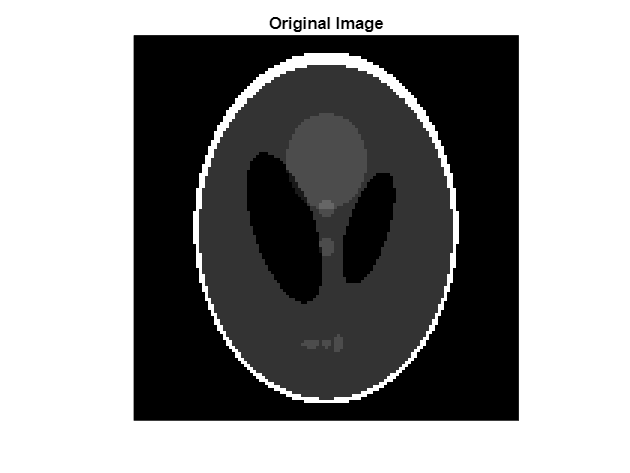

close all

IMG = phantom(N,N);
figure, colormap("gray")
imagesc(IMG), axis('equal'),axis('off'), colormap('gray')
title('Original Image')

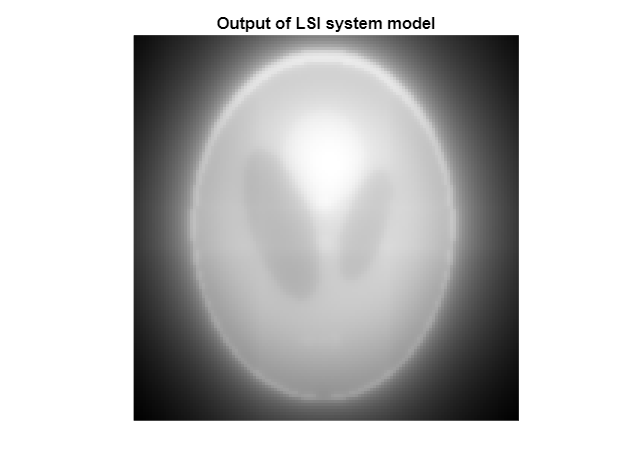

IMG_LSI = conv2(IMG,hb,'same');

figure
imagesc(IMG_LSI), axis('equal'),axis('off'), colormap('gray')
title('Output of LSI system model')
colormap('gray')

Now let's try the projection-backprojection operations on the phantom image, and we'll **vary the number of projections **like we did above.

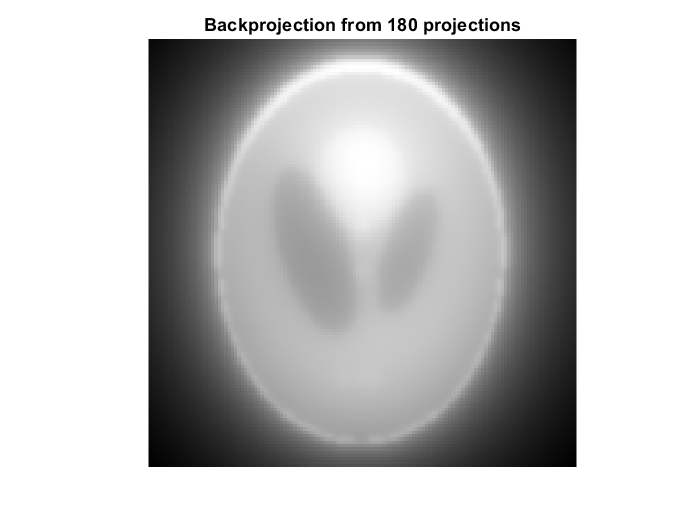

figure, colormap('gray')
for Np = 1:1:180
    kp = [0:180/Np:179];
    [p,r] = radon(IMG,kp);
    fb = iradon(p,kp,'linear','none'); % iradon / backprojections, 'linear' interpolation, 'none' filter
    imagesc(fb), axis('off'), axis('equal')
    title(['Backprojection from ',int2str(Np),' projections'])
    if Np <32
        pause(0.5)
    else
        pause(.05)
    end
    
end

The two images are quite similar although not exactly the same, because we **estimated the point spread functio**n with a finite resolution. 

In "hb", the radon function starts by interpolating the original image

## Filtered Backprojection -- point source image - RESULT = MUCH LESS NOISY

The inverse filter -- that is, a system that inverts the effect of the projection-backprojection system -- can be added to this system. The "Ram-Lak" filter will do this. We will discuss how this filter works in class, but here just know that the `iradon`** function has this filter built-in**.

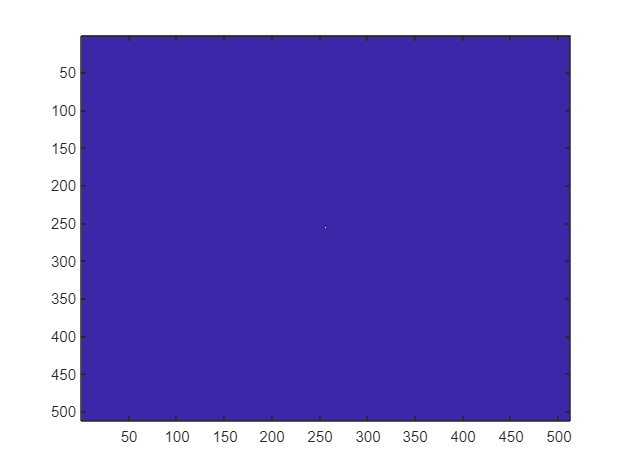

close all
N = 512;
IMGp = zeros(N,N);
IMGp((N)/2,(N)/2) = 1;
imagesc(IMGp)

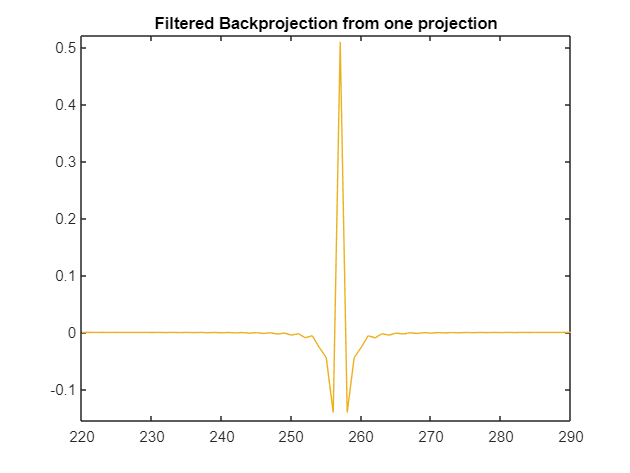

figure, 
[p,r] = radon(IMGp,0); % theta = 0
fb = iradon(p,0,'linear','Ram-Lak'); %'linear' interpolate, 'RamLak' filter inverts the effect of the projection-backprojection system 
plot(fb')
title('Filtered Backprojection from one projection')

xlim([220 290])
ylim([-0.155 0.521])

Now look at the point spread function of FILTERED BP

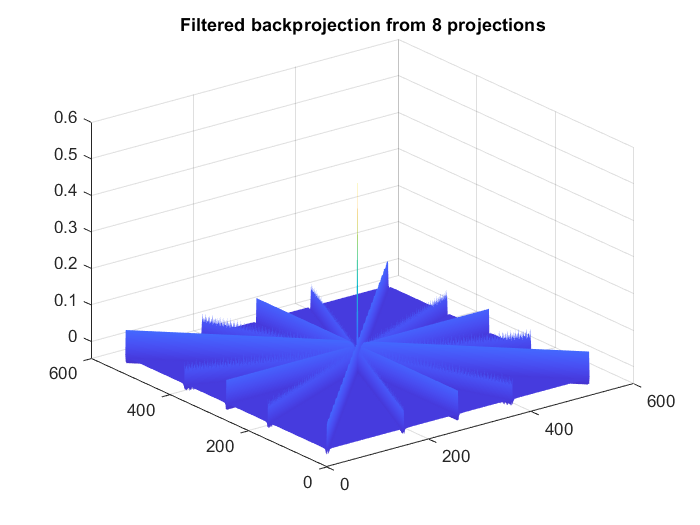

figure, colormap("parula")
for Np = 1:1:180 % chnge projection angles
    kp = [0:180/Np:179];
    [p,r] = radon(IMGp,kp);
    fb = iradon(p,kp,'linear','Ram-Lak');
    h = surf(fb);set(h,'LineStyle','none','FaceColor','interp');
    title(['Filtered backprojection from ',int2str(Np),' projections'])
    if Np <32
        pause(0.5)
    else
        pause(.05)
    end
end

## Filtered Backprojection -- Image Phantom

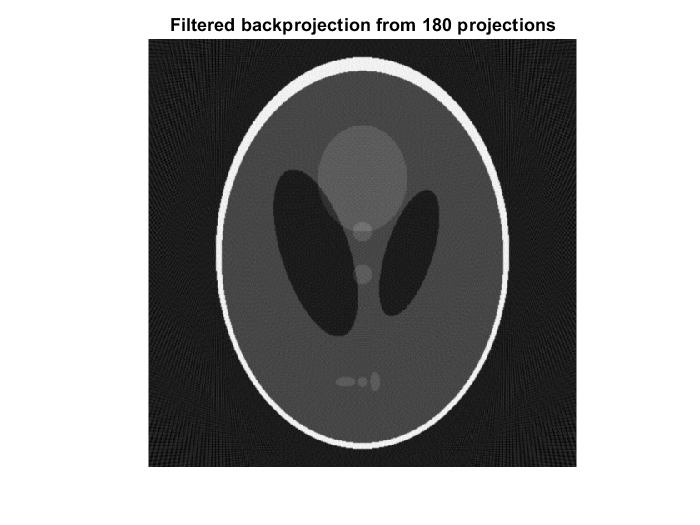

close all
IMG = phantom(N);
figure, colormap(gray)
for Np = 1:1:180
    kp = [0:180/Np:179];
    [p,r] = radon(IMG,kp);
    fb = iradon(p,kp,'linear','Ram-Lak');
    imagesc(fb), axis('off'), axis('equal')
    title(['Filtered backprojection from ',int2str(Np),' projections'])
    if Np <32
        pause(0.5)
    else
        pause(.05)
    end
end

## add Poisson noise to projections

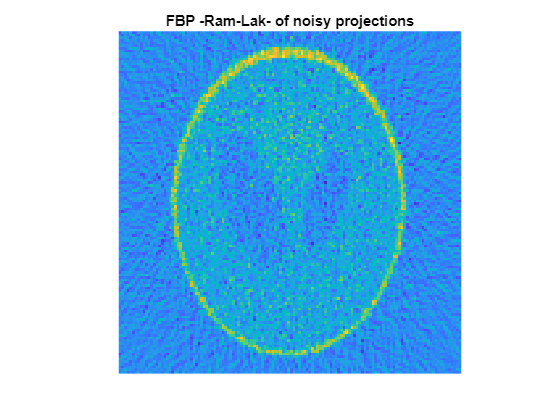

close all

N = 129;
IMG = phantom(N);


figure

kp = [0:179];
p = radon(IMG,kp);

SNR = 1; % try changing this value
pn = poissrnd(SNR*p); % multiply proj w/ SNR

fb = iradon(pn,kp,'linear','Ram-Lak');
imagesc(fb), axis('off'), axis('equal')
title(['FBP -Ram-Lak- of noisy projections'])  % we see lines w/ noise due to back projection ANGLES

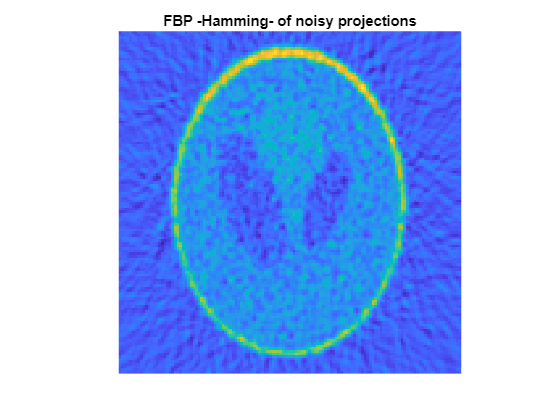

figure
fb = iradon(pn,kp,'linear','Hamming');
imagesc(fb), axis('off'), axis('equal')
title(['FBP -Hamming- of noisy projections'])

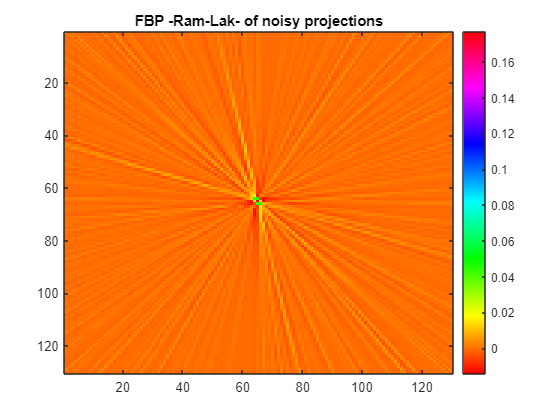


% notice the streaky nature of the noise

% for a better appreciation, look at the case of an point source image
IMGp = zeros(N,N);
IMGp((N+1)/2,(N+1)/2) = 1;


figure, colormap(hsv)

kp = [0:256];
p = radon(IMGp,kp);

SNR = 1; % try changing this value
pn = poissrnd(SNR*p);

fb = iradon(pn,kp,'linear','Ram-Lak');
imagesc(log10(1+fb)); colorbar
title(['FBP -Ram-Lak- of noisy projections'])

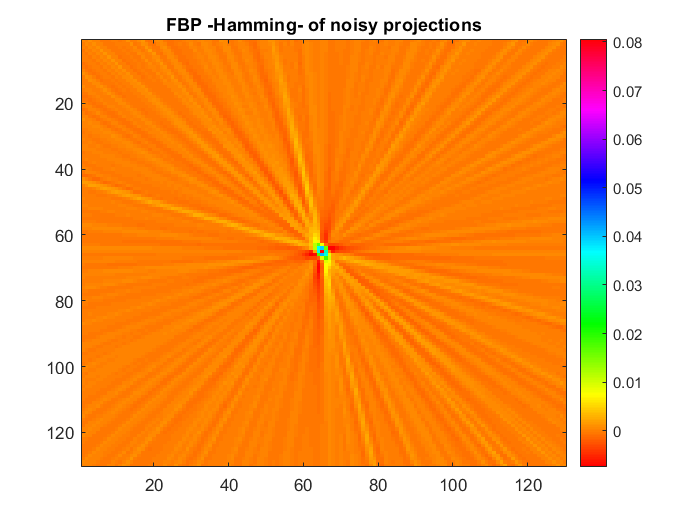


figure, colormap(hsv)
fb = iradon(pn,kp,'linear','Hamming');
imagesc(log10(1+fb)); colorbar
title(['FBP -Hamming- of noisy projections'])